Efterår2016Reeksamen

clearvars
clc
close all

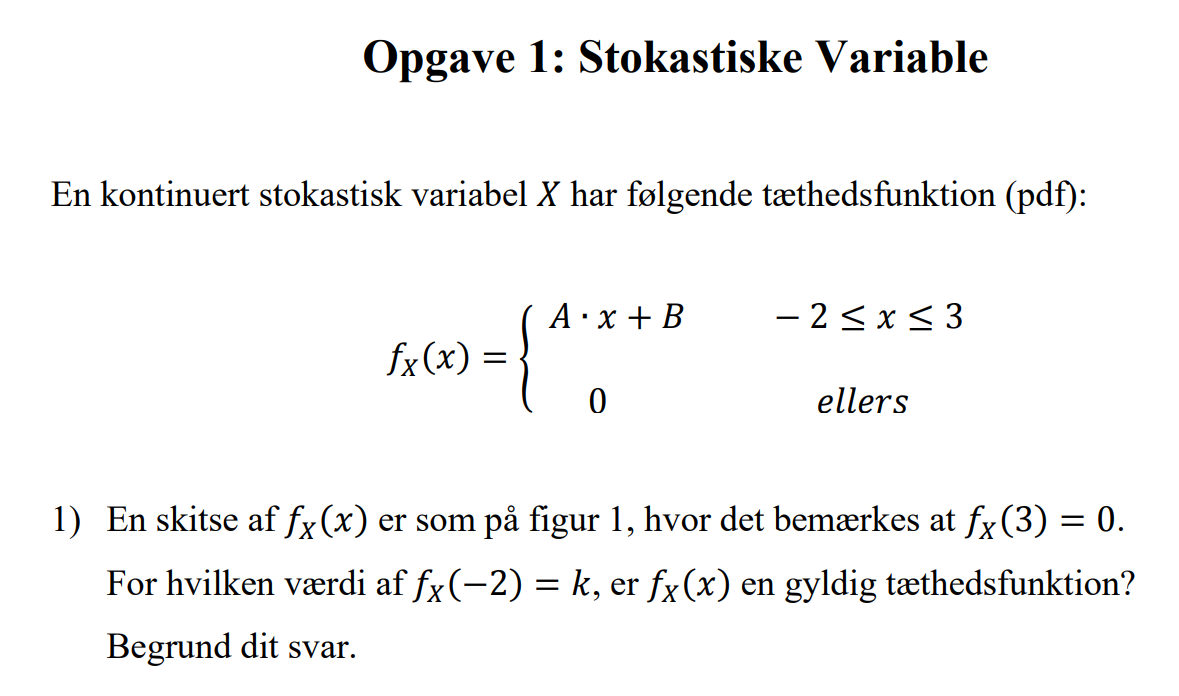

clearvars

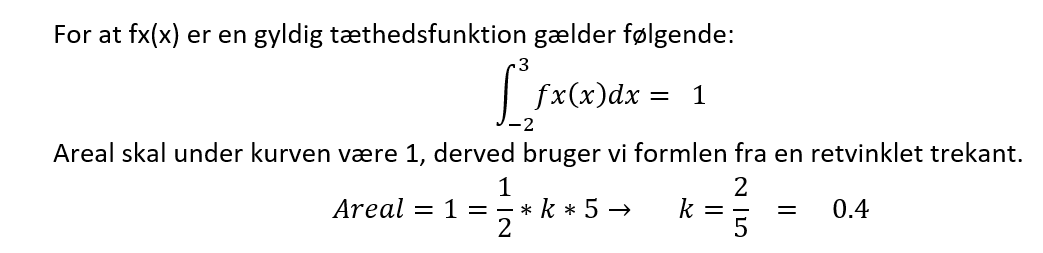

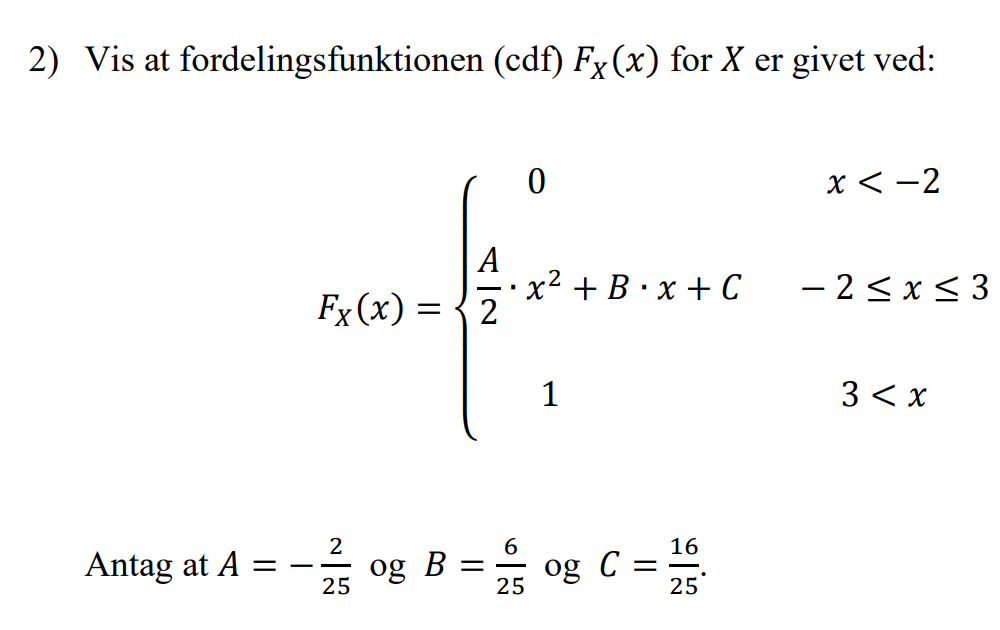

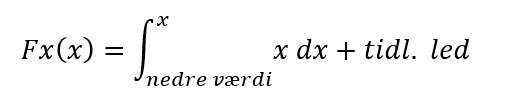

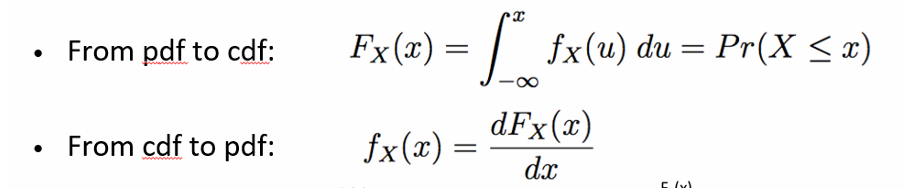

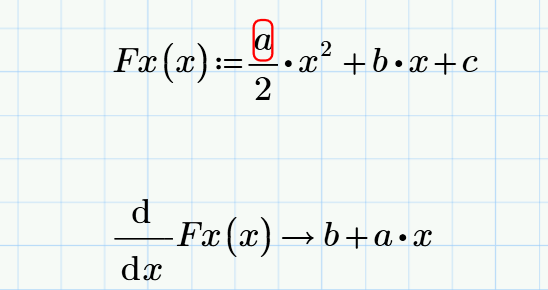

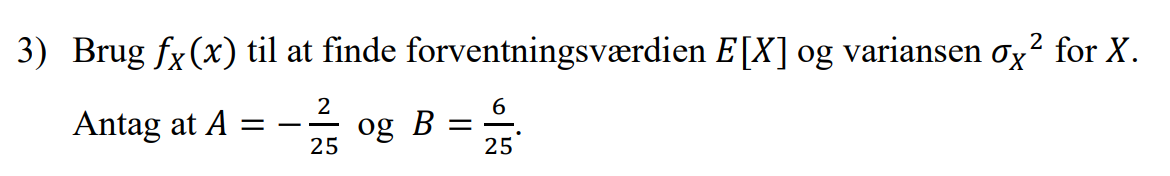

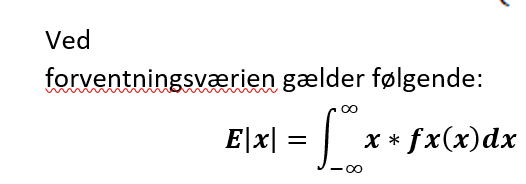

clearvars
syms x
A=-2/25; B = 6 /25;
fx(x) = piecewise( x < -2, 0,...
                    -2 <= x <= 3, A*x+B,...
                    x > 3 ,0)

$$fx(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x<-2\\ \frac{6}{25}-\frac{2\,x}{25} & \text{ if }x\in \left[-2,3\right]\\ 0 & \text{ if }3<x \end{array}\right.$$

                
                  
          ex =  int(x*fx(x), -Inf, Inf)

$$ex = -\frac{1}{3}$$

          ex2 = int(x.^2*fx(x), -Inf, Inf)

$$ex2 = \frac{3}{2}$$

         variance =  ex2-ex^2

$$variance = \frac{25}{18}$$

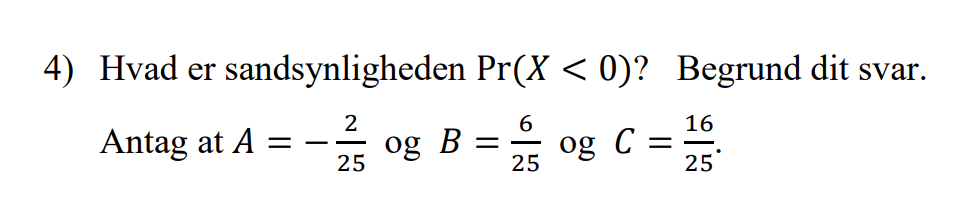

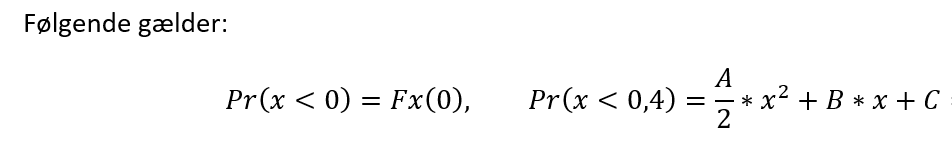

C = 16/25

C = 0.6400

         Fx(x) = piecewise( x < -2, 0,...
                    -2 <= x <= 3, A/2*x^2+B*x+C,...
                    x > 3 ,1)

$$Fx(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x<-2\\ -\frac{x^{2}}{25}+\frac{6\,x}{25}+\frac{16}{25} & \text{ if }x\in \left[-2,3\right]\\ 1 & \text{ if }3<x \end{array}\right.$$

                
         Pr1 = Fx(0)

$$Pr1 = \frac{16}{25}$$

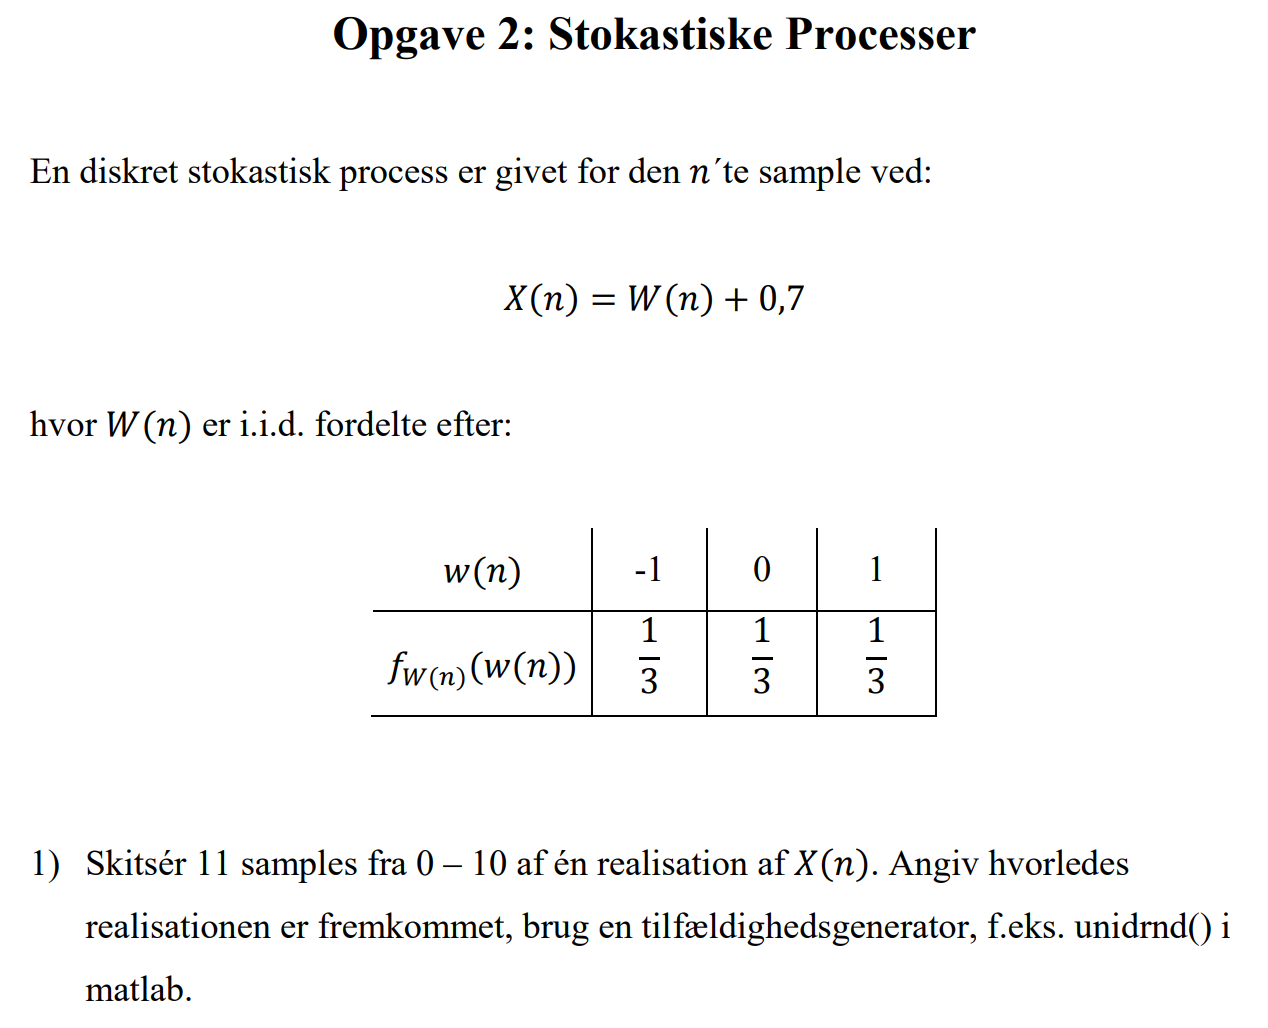

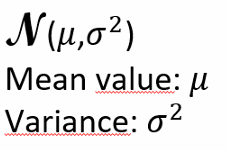

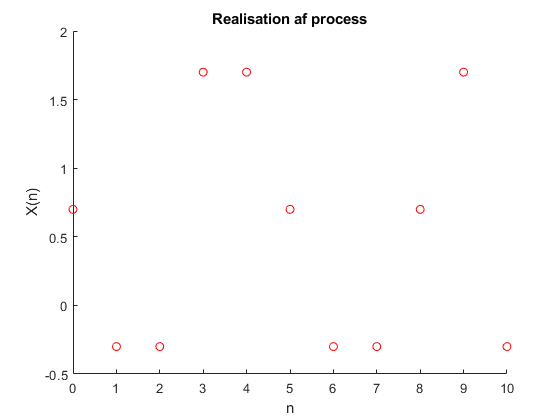

x = 0:1:10;
samples = length(x);
w = unidrnd(3, 1, samples) - 2 + 0.7;
figure(1);
hold on
xlabel("n"); ylabel("X(n)"); title("Realisation af process");
scatter(x, w, 'or')

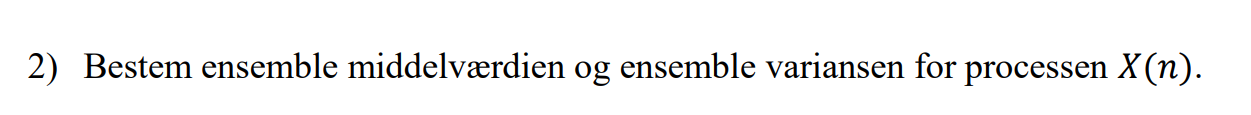

x = [-1 0 1]

x =     -1     0     1


fx= [1/3 1/3 1/3]

fx =     0.3333    0.3333    0.3333


ex = sum(x.*fx)+0.7

ex = 0.7000

ex2= sum(x.^2.*fx)

ex2 = 0.6667

%%%% OBS %%%% Variance giver ikke rigtige svar 

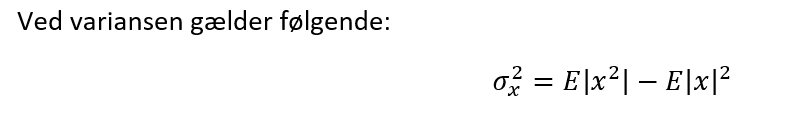

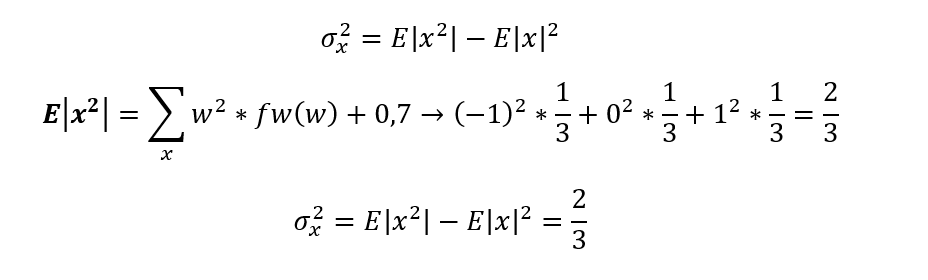

variance2 = ex2 - ex^2

variance2 = 0.1767


$$\mathrm{Rxx}\left(\tau \right)=\sum x\left(n\right)x\left(n-\tau \right)*\mathrm{fx}\left(x\right)$$


hvor $f\left(x\right)=\mathrm{fw}\left(w+0\ldotp 7\right)$

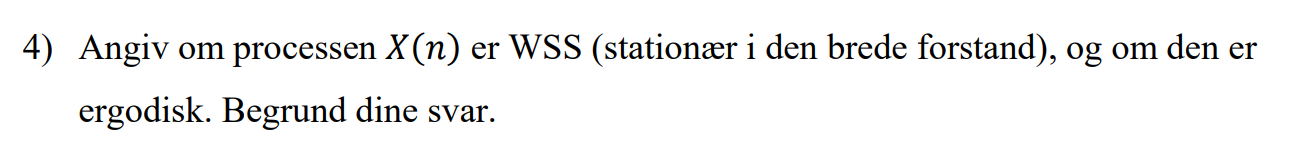

Da processen er uafhængig af tiden, og at middelværdien og variansen ikke ændrer sig over tid, så kan vi konstanter at processen er stationær.

Processen er egodisk da pmf kan bestemmes udfra en realisation

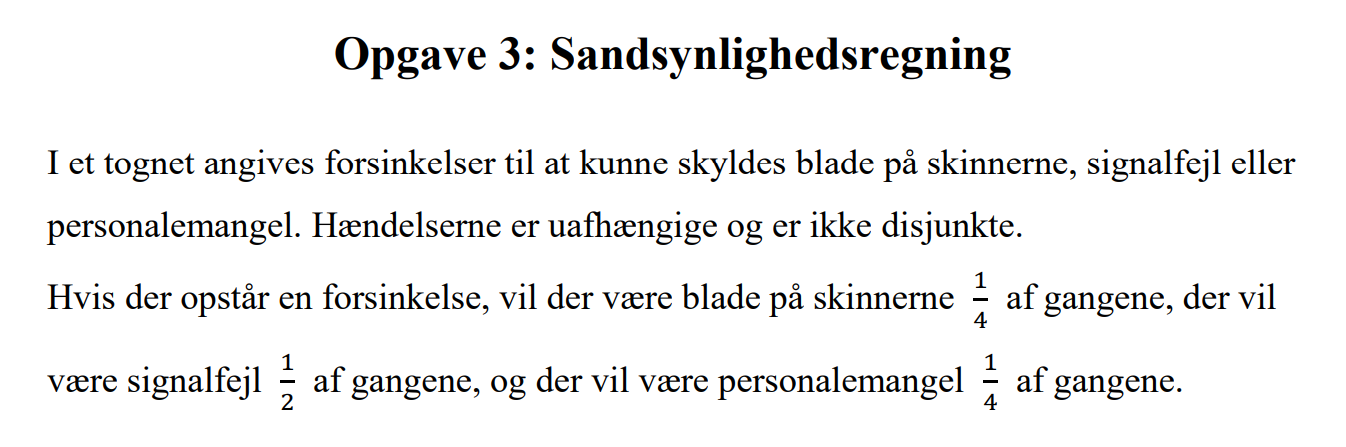

Haendelse A : Blade på skinnerne

Haendelse B: Signal fejl

Haendelse C: Personmangel

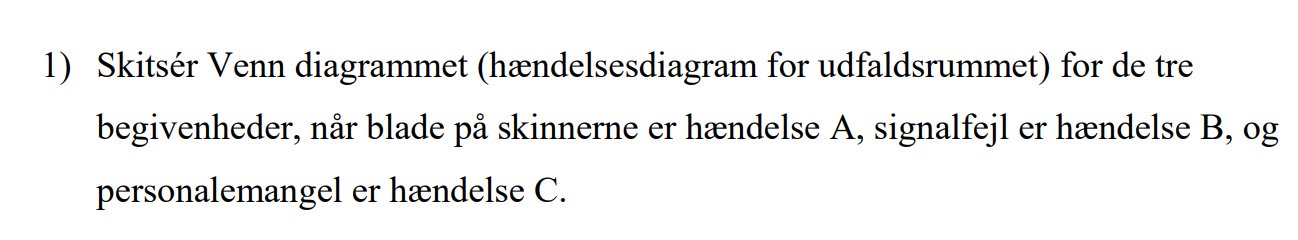

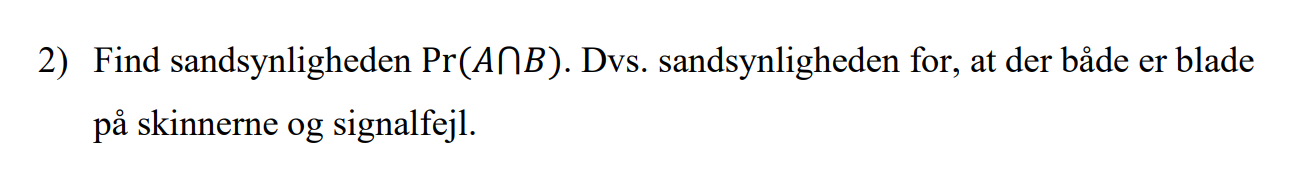

Pr_A = 1/4;
Pr_B = 1/2;
Pr_C = 1/4;

Pr_A_B = Pr_A*Pr_B

Pr_A_B = 0.1250

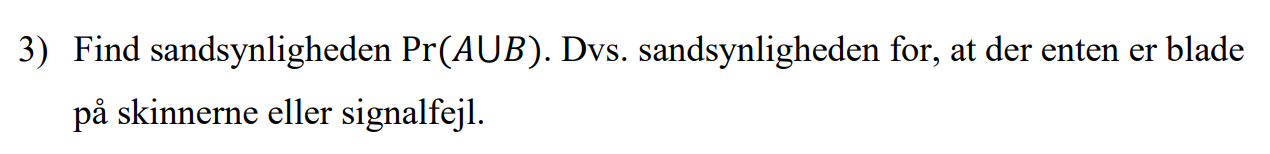

Pr_AUB = Pr_A + Pr_B - Pr_A_B

Pr_AUB = 0.6250

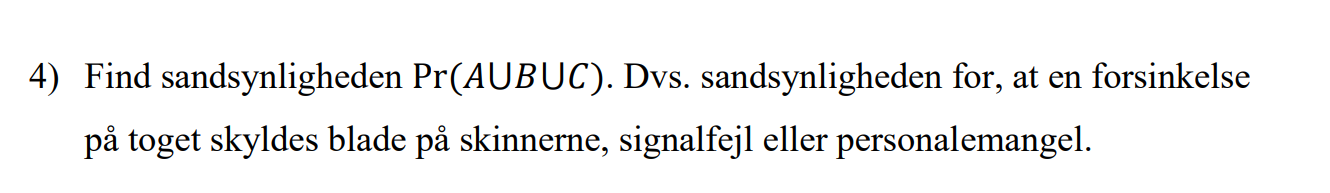

Da A, B og C er uafhængige så tages der Pr(A U B U C) 

Pr_A + Pr_B + Pr_C - Pr_A_B - (Pr_B*Pr_C) - (Pr_A*Pr_C) + (Pr_A*Pr_B*Pr_C)

ans = 0.7188

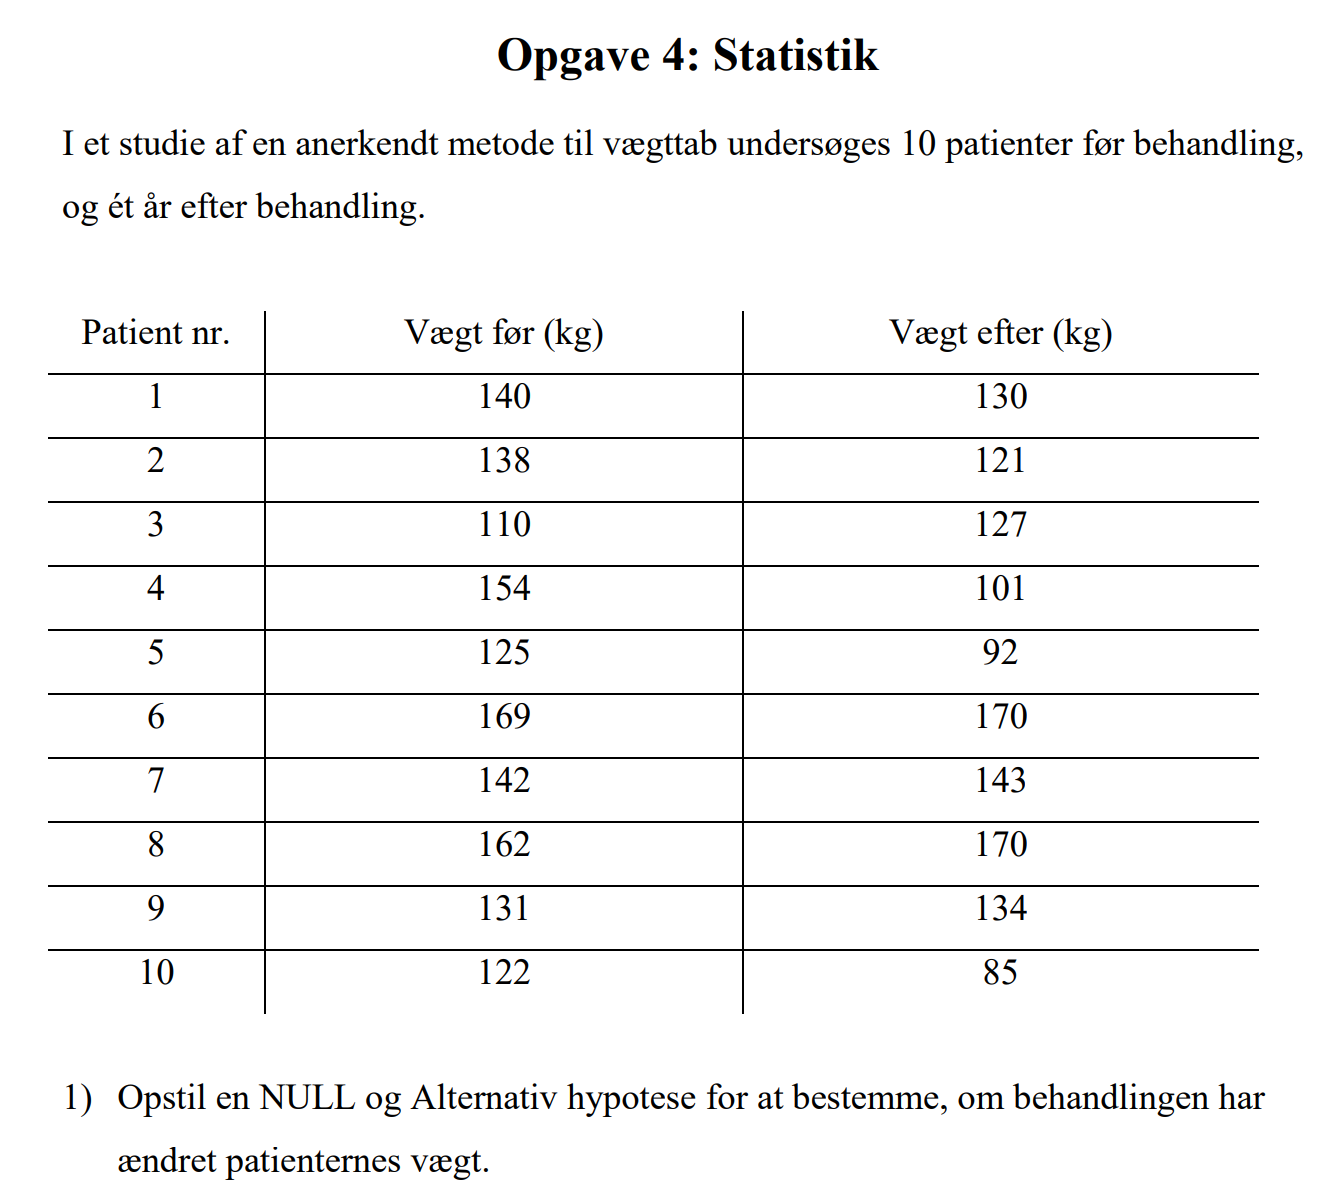

Null hypothesis. Brugt som testen af ingen forskel.


$$H_0 =\mu 1=\mu 2$$


Alternanive hypotese


$$H_1 =\mu 1\not= \mu 2$$


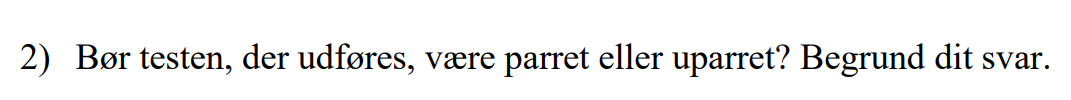

Da det er samme subjekt for før og efter, så bør det være en parret. 

patient = 1:1:10;
foer = [ 140 138 110 154 125 169 142 162 131 122];
efter = [130 121 127 101 92 170 143 170 134 85];

middelforskel = sum(efter-foer)/length(patient)

middelforskel = -12

s2 = 1/(length(patient)-1)*(sum((efter-foer-middelforskel).^2))

s2 = 508.8889

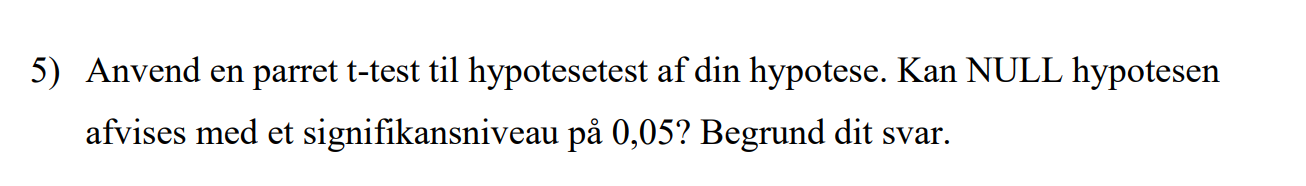

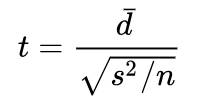

t = middelforskel/sqrt(s2/length(patient))

t = -1.6822

pval = 2*(1-tcdf(abs(t),(length(patient)-1)))

pval = 0.1268

Da pval er større end 0.05, så fejler vi med at afvise hypotese 0. 

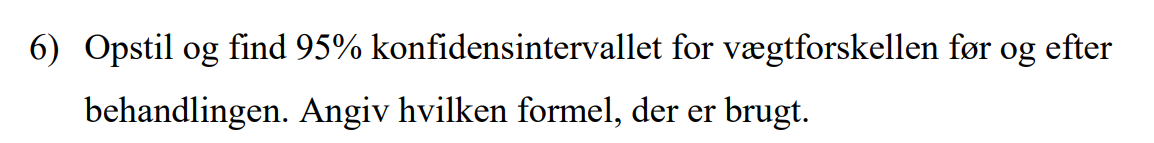

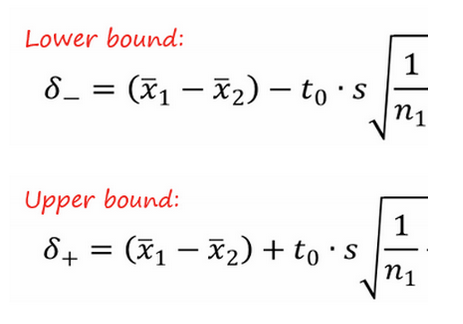

t0=tinv(0.975,(length(patient)-1))

t0 = 2.2622

koefMinus = middelforskel-t0*sqrt(s2)*sqrt((1/length(patient)))

koefMinus = -28.1374

koefPositiv = middelforskel + t0*sqrt(s2)*sqrt((1/length(patient)))

koefPositiv = 4.1374